clear;
syms p C1 C2 B0
%当p<=pt时u的最大值
u_bmax=(2*p*log(-(2*p - C1*C2 + C1*C2*sqrt(-(4*p - C1*C2)/(C1*C2)))/(2*p)) + C1*C2 - 2*B0*C2*p + C1*C2*sqrt(-(4*p - C1*C2)/(C1*C2)))/(2*C2);
b_max=B0 - log(-(2*p - C1*C2 + C1*C2*sqrt(-(4*p - C1*C2)/(C1*C2)))/(2*p))/C2;  %在p<=pt时时有意义
%pt的表达式
pt=C1*C2/4;
%当p>pt时，只会取B0点，此时只会的效用为
ut=C1/2-p*B0;

%导入随机生成的数据
load('20Users_variables.mat', 'E_i', 'r_i', 'B_i');

C1_vec = E_i; %C1_vec(i)为第i个用户的C1参数,C2_vec,B0_vec同理
C2_vec = r_i;
B0_vec = B_i;
C1_len = length(C1_vec);
C2_len = length(C2_vec);
B0_len = length(B0_vec);
if C1_len~=C2_len  || C1_len~=B0_len
    fprintf("输入参数的数量不一致")
end

pt_vec = [];  %pt_vec(i)表示用户i的pt值
ut_vec =cell(1); %ut_vec(i)表示用户i在p>pt时在满意点B0的效用计算公式（当p>pt，满意点收缩到只剩B0一个点）
y_vec=cell(1);  %y_vec(i)表示用户i在 p<=pt 时在满意区间[B0,+inf]最大值的计算公式
bmax_vec=cell(1); %bmax_vec(i)表示用户i 在p<pt时的最大值所对应的带宽值bmax
%生成各个向量
for i=1:C1_len
    tem_pt=subs(pt,[C1,C2],[C1_vec(i),C2_vec(i)]);
    pt_vec=[pt_vec,tem_pt];
    tem_ut=subs(ut,[C1,B0],[C1_vec(i),B0_vec(i)]);
    ut_vec{i}=matlabFunction(tem_ut);
    tem_y = subs(u_bmax,[C1,C2,B0],[C1_vec(i),C2_vec(i),B0_vec(i)]);
    y_vec{i}=matlabFunction(tem_y);
    tem_bmax=subs(b_max,[C1,C2,B0],[C1_vec(i),C2_vec(i),B0_vec(i)]);
    bmax_vec{i} = matlabFunction(tem_bmax);
end
% value = y_vec{1};   %注意读取cell的元数据要用{}
% value(1);
n=1 %变量数目

n = 1

%利用ga进行求解

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


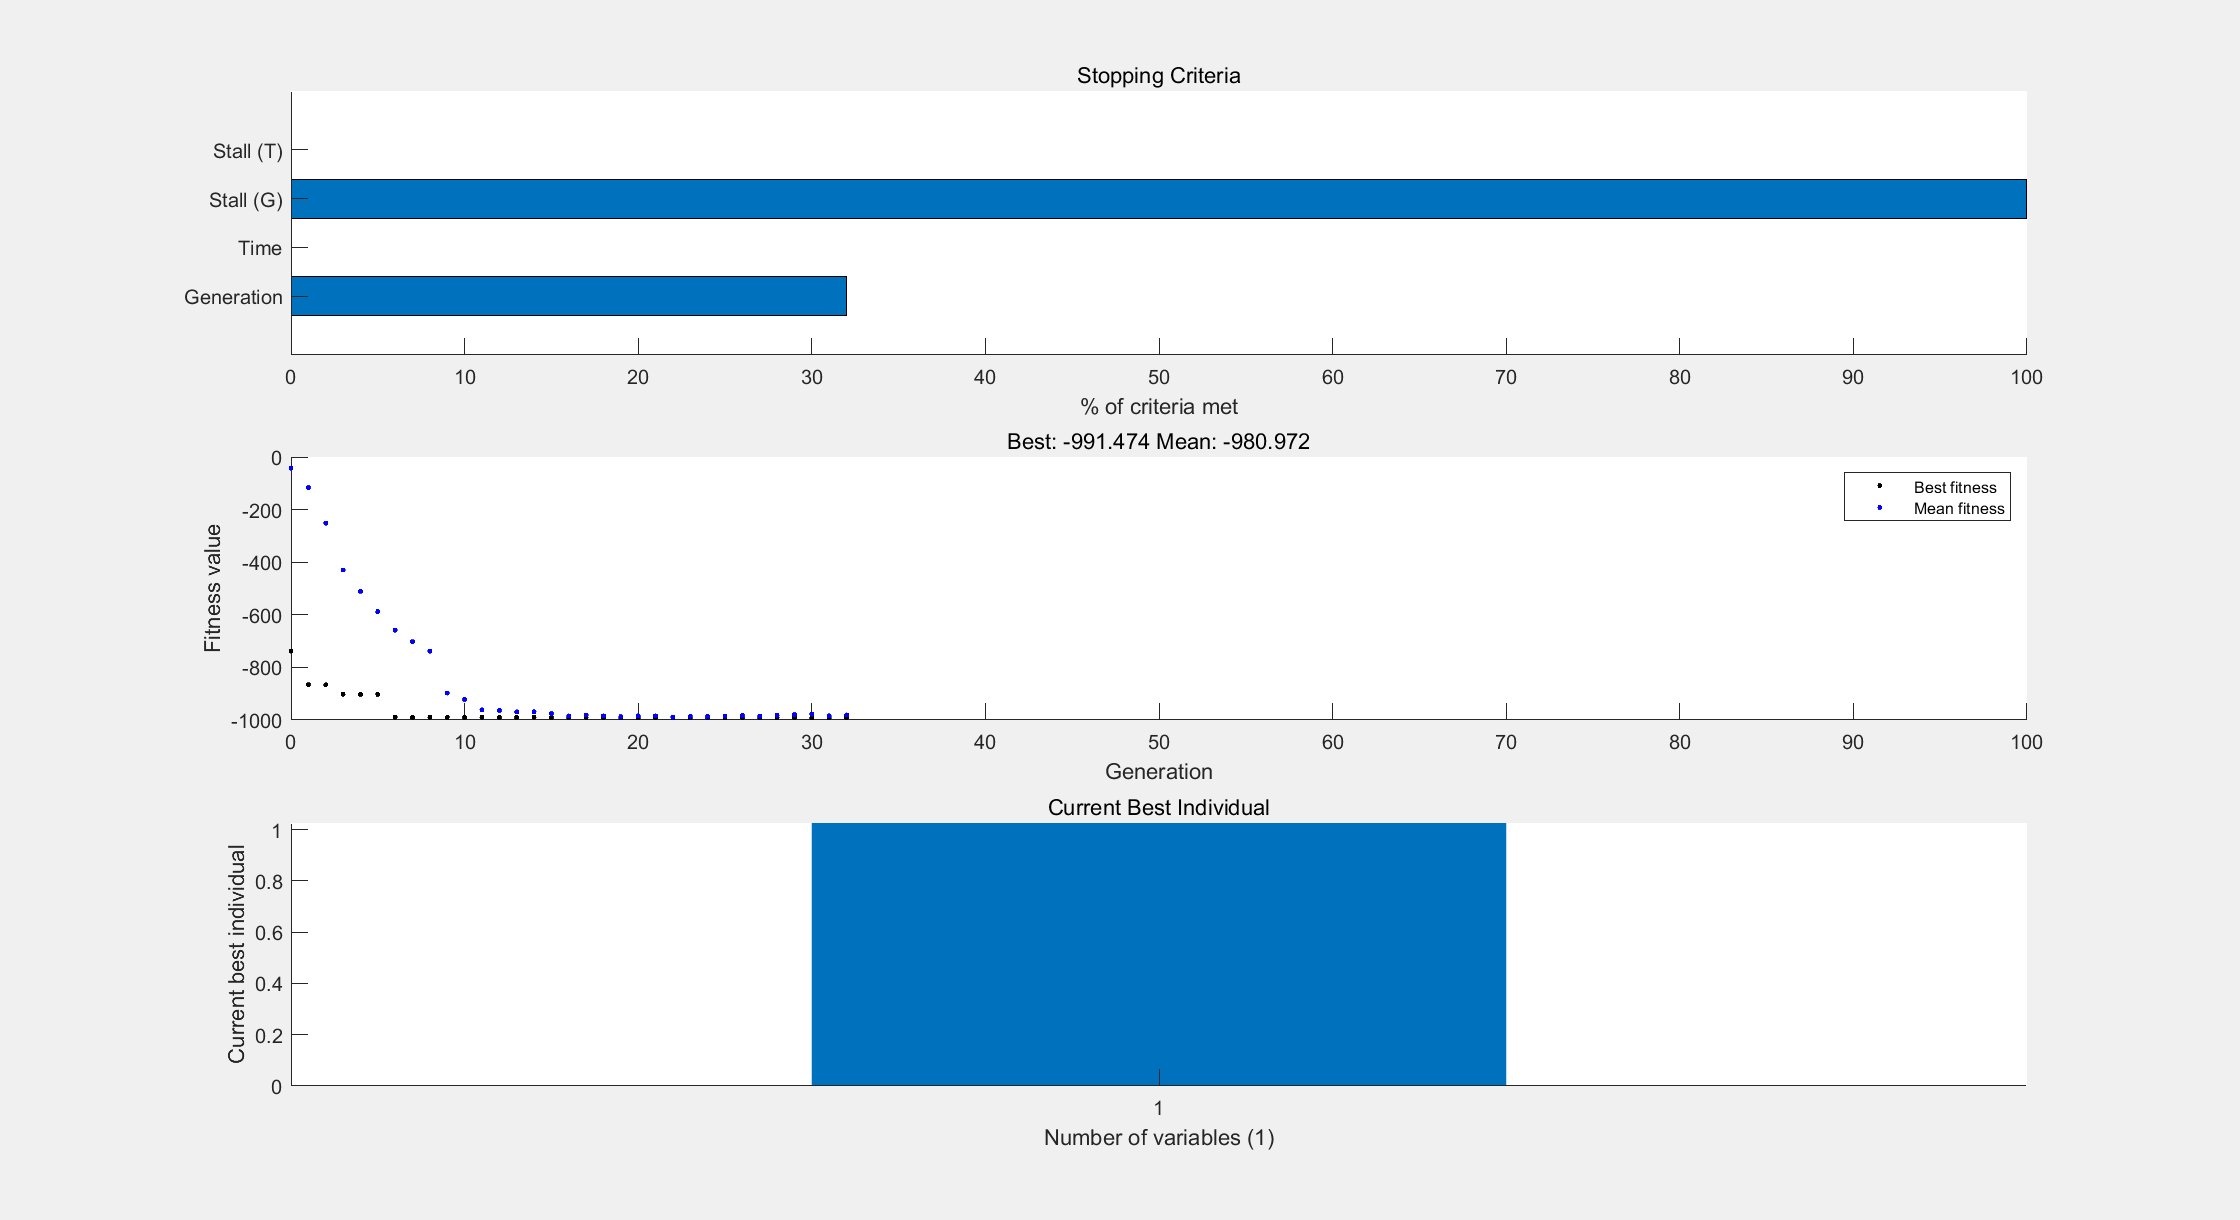

% 将固定参数传递给 objfun
objfun2 = @(price)Revenue_max_func(price,pt_vec,ut_vec,y_vec,B0_vec,...
    bmax_vec);

% 设置非默认求解器选项
options2 = optimoptions("ga","PopulationSize",50,"MaxStallGenerations",10,...
    "PlotFcn",["gaplotstopping","gaplotbestf","gaplotbestindiv"]);

% 求解
[solution,objectiveValue] = ga(objfun2,n,[],[],[],[],zeros(n,1),[],[],[],...
    options2);


% 清除变量
clearvars objfun2 options2


